# Demo of 2D CNN-ATTENTION-LSTM

clc;clear;close all

load NASAtrain.mat
data = [train1.data; train2.data; train3.data; train4.data];
labels = [train1.label; train2.label; train3.label; train4.label];
numAll = length(labels)

numAll = 636

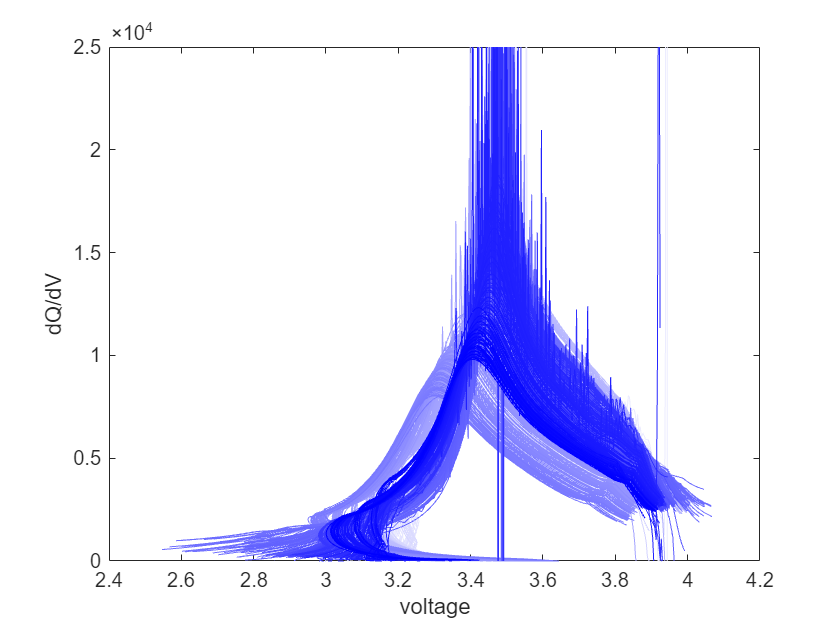

% data display
r_step = 255./numAll; 
r = 0: r_step :255;
r = flip(r);
b = 255;
g=0: r_step :255;
g = flip(g);


figure(1)
for i = 1:1:numAll
plot(smoothdata(data{i}(1,:)),smoothdata(data{i}(2,:),"gaussian"),'color',[r(i) g(i) b]/255)
hold on 
end
xlabel('voltage')
ylabel('dQ/dV')
ylim([0 2.5e4])
hold off

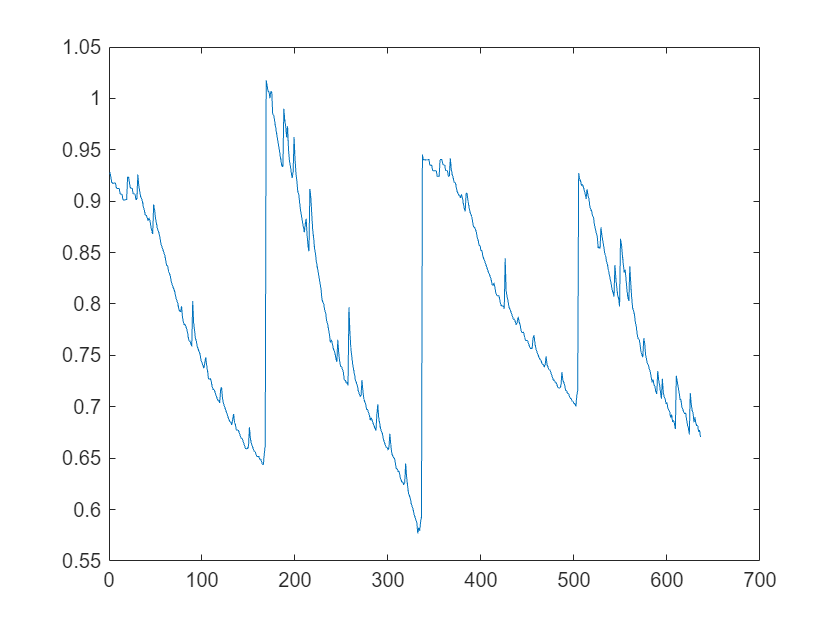


figure(2)
plot(labels)

## NN training

[idxTrain,idxValidation,idxTest] = trainingPartitions(numAll, [0.8 0.1 0.1]);

XTrain = data(idxTrain);
TTrain = labels(idxTrain);

XValidation = data(idxValidation);
TValidation = labels(idxValidation);
numValidation = length(idxValidation);

XTest = data(idxTest);
TTest = labels(idxTest);

numfeatures = 3

numfeatures = 3

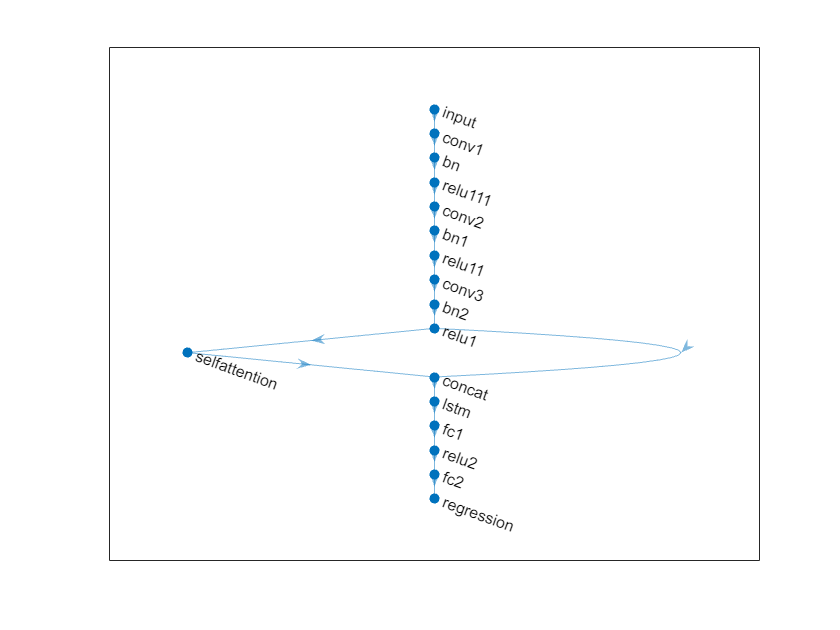


%% 定义输入层 CNN-SelfAttention-LSTM模型
inputLayer = sequenceInputLayer(numfeatures, 'Name', 'input');

% 定义卷积块
convBlock = [
    convolution1dLayer(3, 16, 'Padding', 'same', 'Name', 'conv1')% 一维卷积层，小核
    batchNormalizationLayer('Name', 'bn') % 批量归一化层
    reluLayer('Name', 'relu111') % Relu激活层
    convolution1dLayer(5, 32, 'Padding', 'same', 'Name', 'conv2')% 一维卷积层，中核
    batchNormalizationLayer('Name', 'bn1') % 批量归一化层
    reluLayer('Name', 'relu11') % Relu激活层
    convolution1dLayer(7, 64, 'Padding', 'same', 'Name', 'conv3')% 一维卷积层，大核
    batchNormalizationLayer('Name', 'bn2') % 批量归一化层
    reluLayer('Name', 'relu1')  % Relu激活层
    ];

% 定义自注意力层
attentionLayer = selfAttentionLayer(4,40,"Name","selfattention");%Self-Attention机制 多头数为4 qkv三个的维度都为40 该层命名为selfattention

% 定义LSTM层
lstmLayer = lstmLayer(64, 'OutputMode', 'last', 'Name', 'lstm'); % LSTM层

% 定义全连接和回归层
fcLayers = [
    fullyConnectedLayer(20, 'Name', 'fc1')% 全连接层
    reluLayer('Name', 'relu2') % Relu激活层
    fullyConnectedLayer(1, 'Name', 'fc2')% 全连接层
    regressionLayer('Name', 'regression')% 回归层
    ];

% 创建一个层图
lgraph = layerGraph(inputLayer);

% 添加层到图中
lgraph = addLayers(lgraph, convBlock);
lgraph = addLayers(lgraph, attentionLayer);
lgraph = addLayers(lgraph, lstmLayer);
lgraph = addLayers(lgraph, fcLayers);

% 创建一个深度学习网络层阵列，拼接 CNN 和 SelfAttention 输出
concatLayer = concatenationLayer(1, 2, 'Name', 'concat');

% 将拼接层添加到图中
lgraph = addLayers(lgraph, concatLayer);

% 连接层
lgraph = connectLayers(lgraph, 'input', 'conv1');
lgraph = connectLayers(lgraph, 'relu1', 'selfattention/in');
lgraph = connectLayers(lgraph, 'relu1', 'concat/in1');
lgraph = connectLayers(lgraph, 'selfattention', 'concat/in2');

% 将拼接层的输出连接到 LSTM 层
lgraph = connectLayers(lgraph, 'concat', 'lstm');

% 最后连接到全连接层
lgraph = connectLayers(lgraph, 'lstm', 'fc1');

% 绘制图形来检查结构
figure;
plot(lgraph)

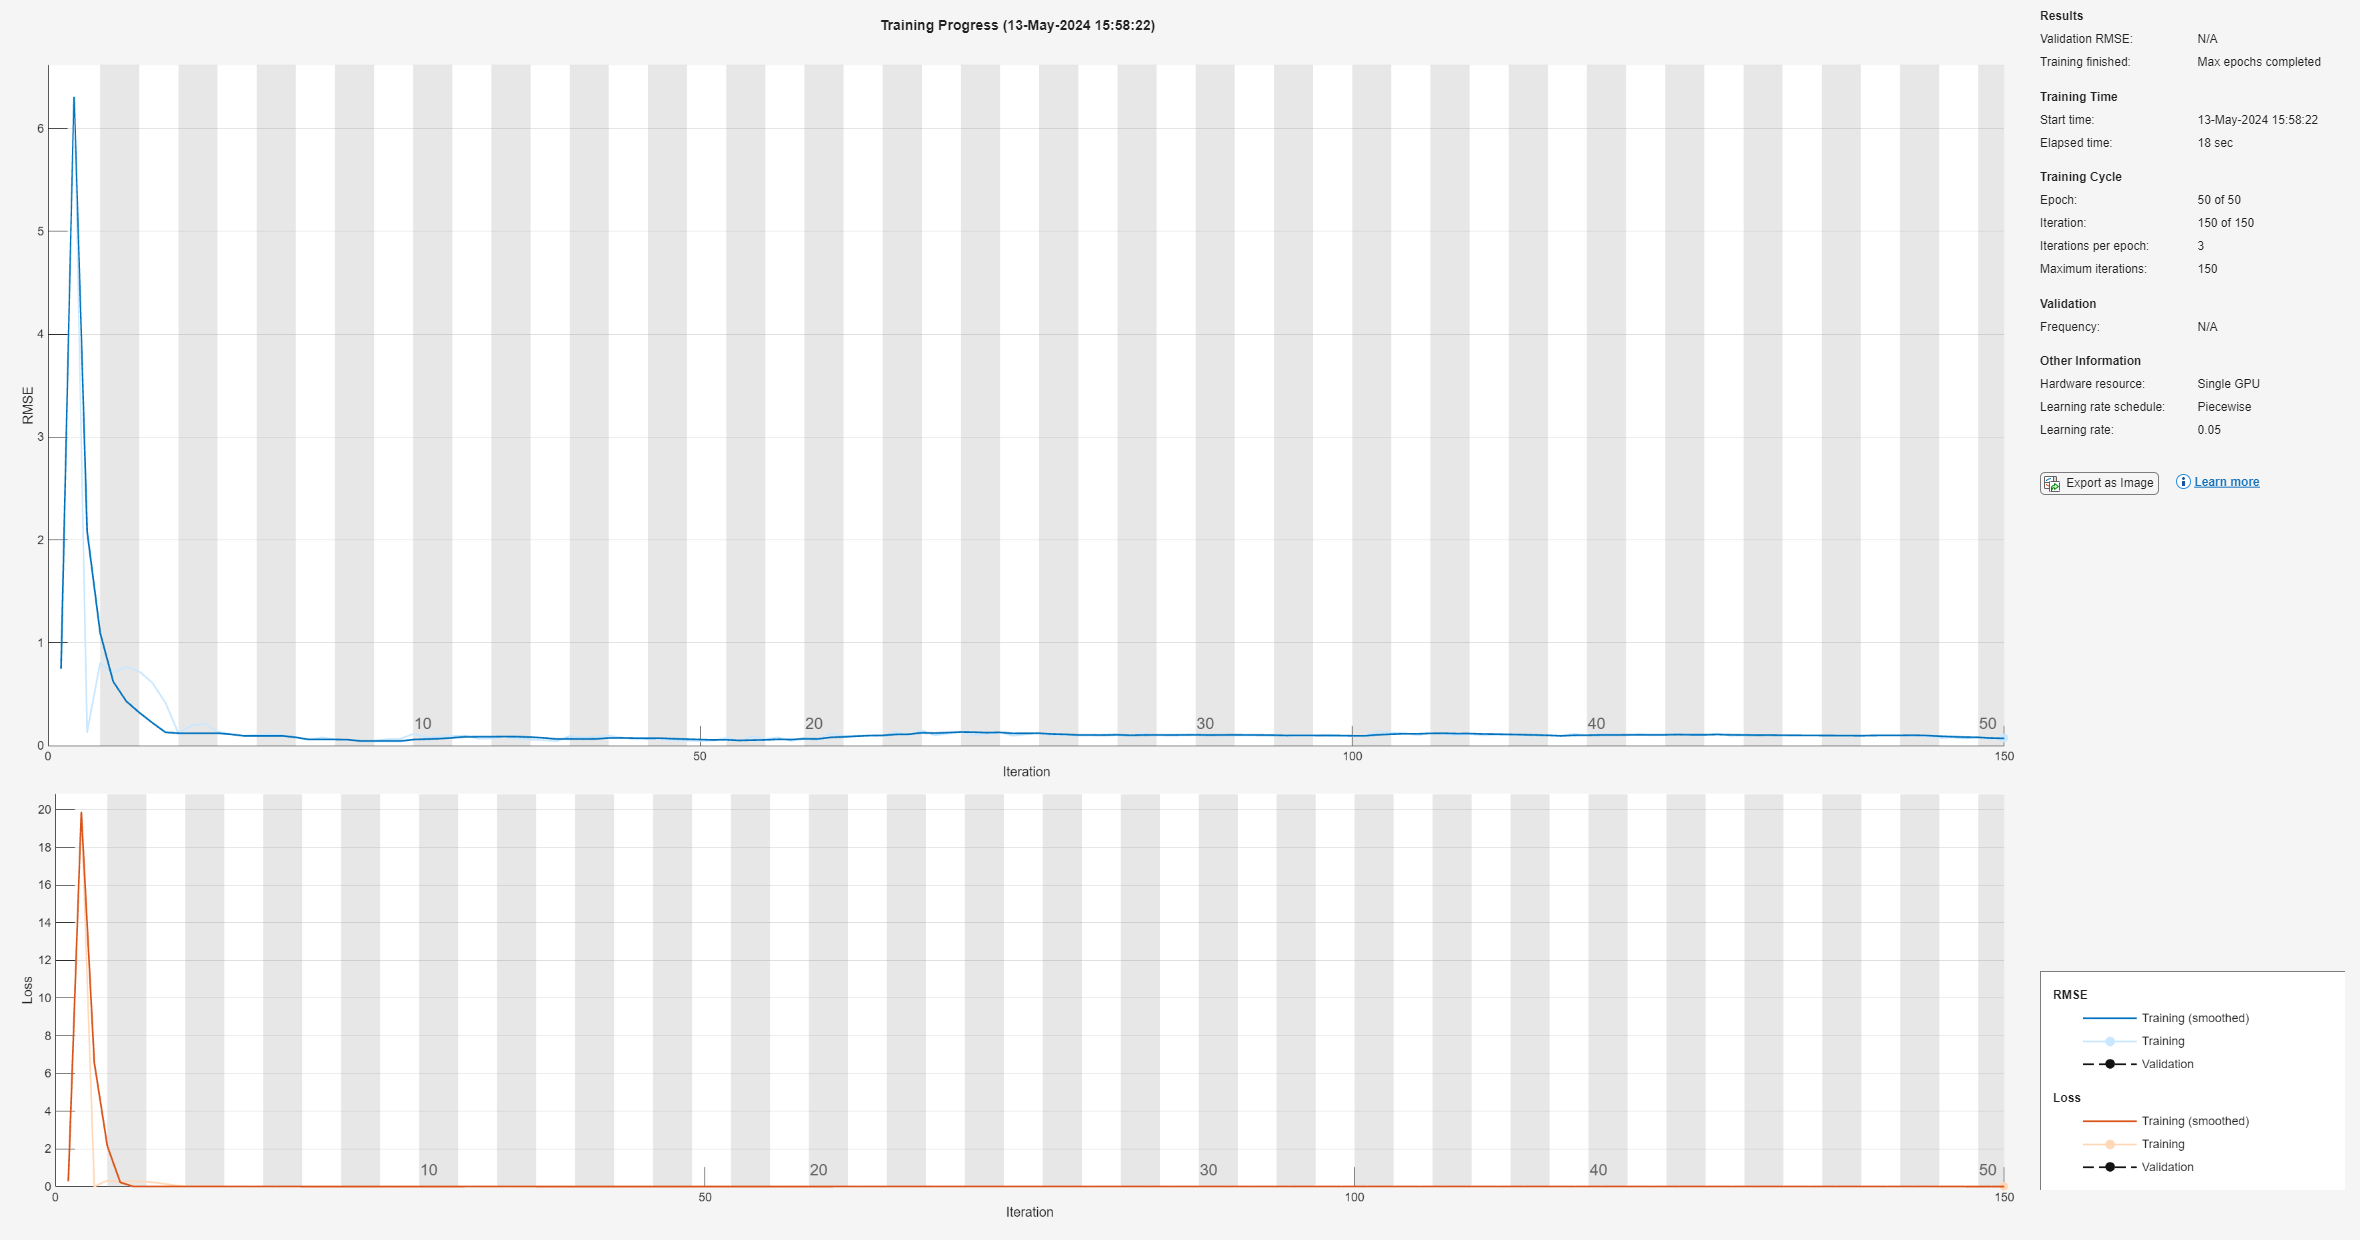


%%  参数设置
options = trainingOptions('adam', ...      % Adam 梯度下降算法
    'MaxEpochs', 50, ...                 % 最大迭代次数
    'InitialLearnRate', 0.05, ...          % 初始学习率为 0.01
    'LearnRateSchedule', 'piecewise', ...  % 学习率下降
    'LearnRateDropFactor', 0.1, ...        % 学习率下降因子
    'LearnRateDropPeriod', 1200, ...       % 经过 1200 次训练后 学习率为 0.01 * 0.1
    'Shuffle', 'every-epoch', ...          % 每次训练打乱数据集
    'Plots', 'training-progress', ...      % 画出曲线
    'Verbose', false);

%%  训练模型
net = trainNetwork(XTrain, TTrain, lgraph, options);


%%  仿真预测
t_sim1 = predict(net, XValidation);
t_sim2 = predict(net, TValidation );

Error using DAGNetwork/predict (line 195)
The prediction sequences are of feature dimension 63 but the input layer expects sequences of feature dimension 3.




%%  均方根误差
error1 = sqrt(sum((t_sim1' - TValidation).^2) ./ numValidation);


%%  查看网络结构
analyzeNetwork(net)



function varargout = trainingPartitions(numObservations,splits)
%TRAININGPARTITONS Random indices for splitting training data
%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
%   random vectors of indices to help split a data set with the specified
%   number of observations, where SPLITS is a vector of length N of
%   partition sizes that sum to one.
%
%   Example: Get indices for 50%-50% training-test split of 500
%   observations.
%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
%
%   Example: Get indices for 80%-10%-10% training, validation, test split
%   of 500 observations. 
%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])

arguments
    numObservations (1,1) {mustBePositive}
    splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
end

numPartitions = numel(splits);
varargout = cell(1,numPartitions);

idx = randperm(numObservations);

idxEnd = 0;

for i = 1:numPartitions-1
    idxStart = idxEnd + 1;
    idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

    varargout{i} = idx(idxStart:idxEnd);
end

% Last partition.
varargout{end} = idx(idxEnd+1:end);

end

function mustSumToOne(v)
% Validate that value sums to one.

if sum(v,"all") ~= 1
    error("Value must sum to one.")
end

end
